close all
clear

**QUESTION 1: Look at all the images at data/input and check that they all contain a chessboard pattern. How many calibration images are there?**

39

**QUESTION 2: Also check the chessboard parameters to match the shape of the chessboard in your images. How many chessboard inner corners, (columns, rows) is speci�ed in find_points.py? What is the chessboard tile size? **

6 col, 8 rows

Tile size 0.03475

**QUESTION 3: In Matlab, plot the model points and draw lines between them. Check that they are given in a zig-zag pattern. How many model points are there and do they agree with the number of chessboard inner corners speci�ed in find_points.py? **

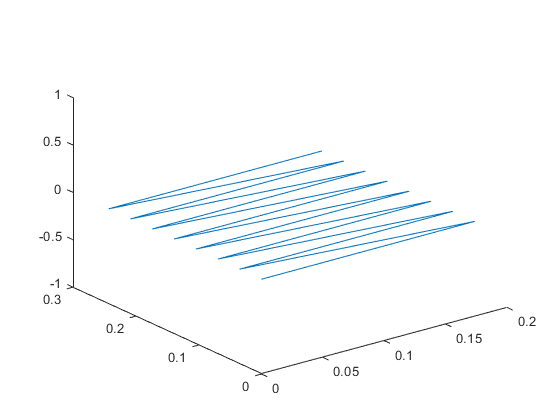

load('35.mat')
figure
plot3(model_points(:,1),model_points(:,2),model_points(:,3))

48 points = 6x8, ok

**QUESTION 4: How many calibration points are there in each output image?**

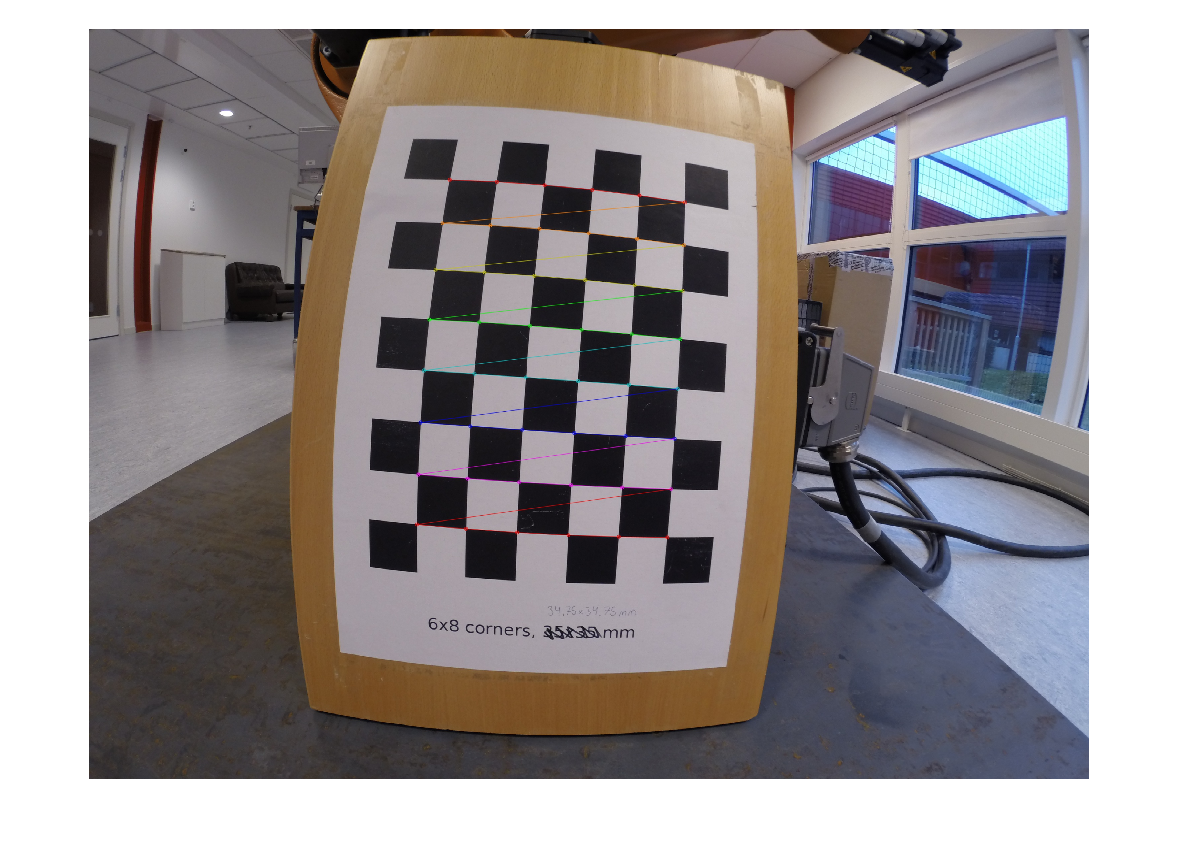

tmpim = imread('F:\kurser\master\tsbb09\Lab 3\data\output\23.jpg');
figure
imshow(tmpim)

48

**QUESTION 5: What values do you get in the A-matrix, the distortion coe�cients, and RSME for reprojection, rpe?**


$$A=\left\lbrack \begin{array}{ccc}
1335\ldotp 601 & 0 & 1531\ldotp 976\\
0 & 1344\ldotp 081 & 1101\ldotp 051\\
0 & 0 & 1
\end{array}\right\rbrack$$


Dist coeff$\;=\left\lbrack \begin{array}{cccccc}
-0\ldotp 242 & 0\ldotp 068 & 0 & 0 & 0 & 0\ldotp 009
\end{array}\right\rbrack$

rpe : 0.47 pixels

**QUESTION 6: Zhang's method estimates two distortion coe�cients, but calibrate.py, which is an extension of Zhang's method, returns more than two. What are these additional parameters?**

k1 to k6 are radial distortion coefficients while p1 and p2 are tangential distortion coefficients.

addpath(genpath('F:\kurser\master\tsbb09\Lab 3'));

[cb_inner_corners, cb_tile_size, im_size, model_points, image_points] = load_calibration_input('F:\kurser\master\tsbb09\Lab 3\data\output')

cb_inner_corners = 1×2 int64 row vector
   6   8


cb_tile_size = 0.0348

im_size = 1×2 int64 row vector
   3000   2250


model_points = 39×1 cell array
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}
    {3×48 double}


image_points = 39×1 cell array
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}
    {2×48 double}


[A, d, Rs, ts, rpe] = load_calibration('calibration_cv.mat')

A = 	1.0e+03 *

    1.3356         0    1.5320
         0    1.3441    1.1011
         0         0    0.0010


d =    -0.2419    0.0679   -0.0002    0.0001   -0.0089


Rs = 39×1 cell array
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}
    {3×3 double}


ts = 39×1 cell array
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}


rpe = 0.4724

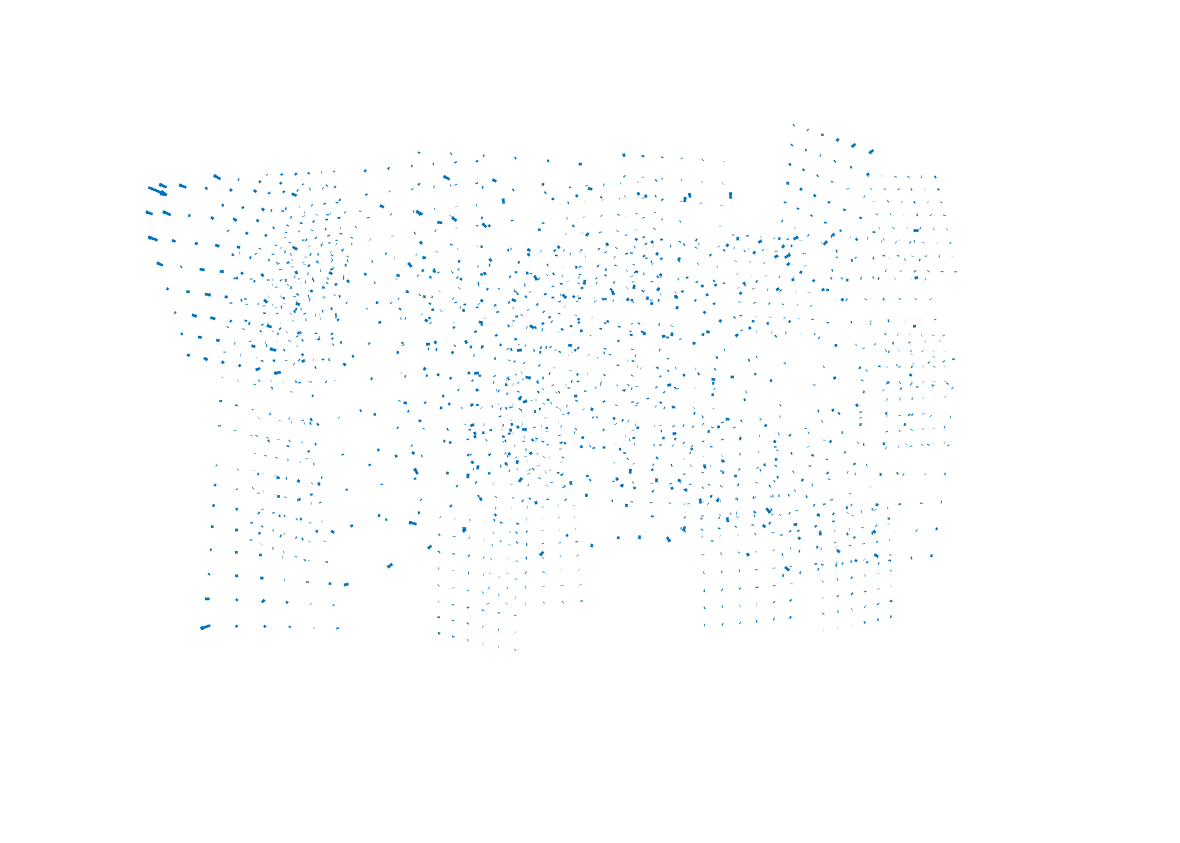

plot_reprojection_errors(im_size, A, d, Rs, ts, model_points, image_points)

**QUESTION 7: Display the reprojection error plot. Which calibration point has the worst reprojection error? Why is that, do you think?**

We get largest error up in the far left corner, likely due to radial distortion.

**QUESTION 8: The function reprojection_errors computes reprojection errors of all points in the calibration. Call it and plot a histogram (histogram(..., 100, 'BinLimits', [0,5])) of the output. At which error interval is the peak located? How is this value related to the RSME for reprojection, rpe? **

rpes1 = reprojection_errors(A, d, Rs, ts, model_points, image_points)

rpes1 =     0.2885    0.0643    0.2922    0.2236    0.3905    0.2924    0.1656    0.1151    0.2695    0.2259    0.1730    0.1136    0.0965    0.1294    0.2913    0.0657    0.0944    0.1087    0.2864    0.1874    0.3393    0.1720    0.3023    0.2086    0.2340    0.1971    0.2370    0.1021    0.1144    0.2216    0.1834    0.0369    0.2061    0.0225    0.0895    0.0707    0.3529    0.0785    0.1170    0.1343    0.1184    0.1975    0.3888    0.1954    0.1784    0.2955    0.2770    0.3154    0.2637    0.2151


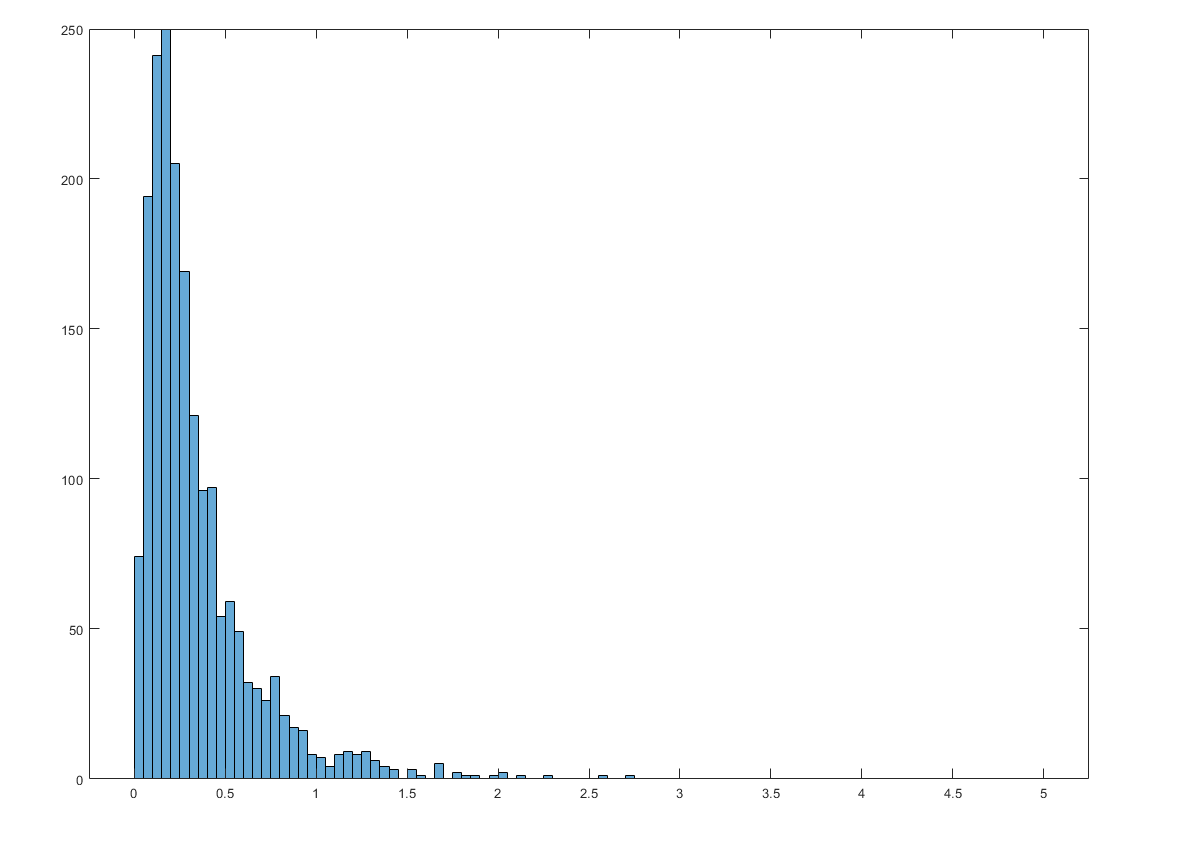

histogram(rpes1, 100, 'BinLimits', [0,5])


sqrt(mean(rpes1.^2))

ans = 0.4724

Peak is around 0.2.

**QUESTION 9: Look up undistort_image and use it on one of the calibration images. (We suggest '14.jpg'). Display both the original and the resulting image. What do you see? Use a digital or physical ruler.**

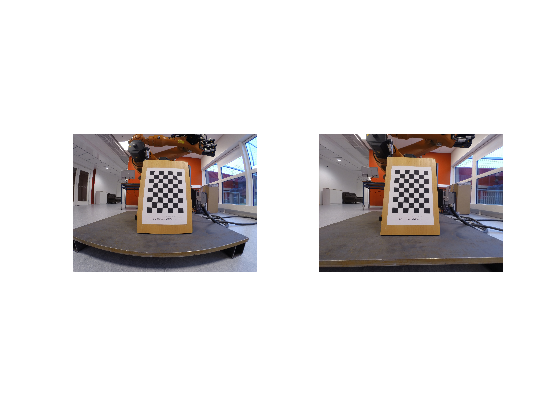

im = imread('14.jpg');
im2 = undistort_image(A, d, im, A);
figure; 
subplot(1,2,1)
imshow(im)
subplot(1,2,2)
imshow(im2)

**QUESTION 10: Modify the last parameter (B) in undistort_image so that it produces a "zoomed out" image, by scaling some elements (which ones?). Display the results. What do you see?**

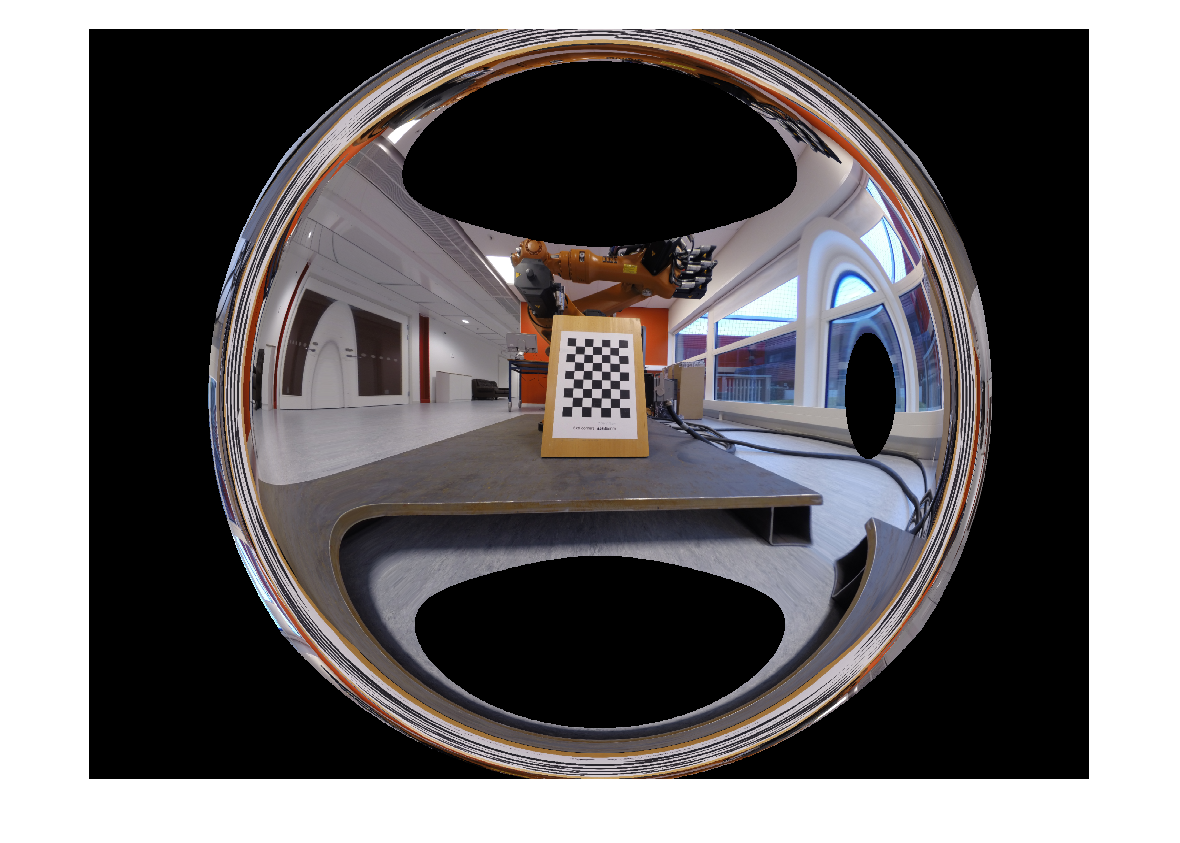

B = A .*   [1/3,1  ,1;
            1,  1/3,1;
            1,  1,  1];
im3 = undistort_image(A, d, im, B);
figure
imshow(im3)

A very distorted image outside of the non-zoomed calibrated image

**QUESTION 11: First look at the Matlab function find_homography.m. Is it the homogeneous or inhomogeneous solution?**

Homogeneous solution

calibrate

    0.0016

   -0.0063

--- Zhang's calibration ---

Intrinsic matrix:
   1.0e+03 *

    1.3776   -0.0023    1.4926
         0    1.3847    1.0638
         0         0    0.0010

Distortion coefficients:
   -0.2130    0.0374

Mean reprojection error: 1.08 pixels


**QUESTION 12: What values do you get in the A-matrix and the radial distortion coeffcients?**

`A = ``3×3`

`10``3`` ×`

`    1.3776   -0.0023    1.4926`

`         0    1.3847    1.0638`

`         0         0    0.0010`

`d = ``1×2`

`   -0.2130    0.0374`

**QUESTION 13: Call reprojection_errors and calculate RSME for reprojection, rpe2?**

rpe2 = rpe

rpe2 = 1.0806

`rpe2 = 1.0806`

**QUESTION 14: Comment out refine_homography. How does A change?**

`A_nonrefined = ``3×3`

`10``3`` ×`

`    1.7891   -0.0283    1.5106`

`         0    1.7424    1.0166`

`         0         0    0.0010`

**QUESTION 15: Compare A before and after refine_calibration. Try to explain the difference. **

The non-refined matrix has larger skew and higher scaling but we do not want that high of a skew so we refine it.

**QUESTION 16: Compare the reprojection errors for your Zhang implementation with the reprojection errors from the previous implementation in OpenCVs, by plotting them in a histogram. Tip: To show two histograms of rpes1 and rpes2 in the same figure: histogram(rpes1, 100, 'displaystyle', 'stairs', 'BinLimits', [0,5]); hold on; histogram(rpes2, 100, 'displaystyle', 'stairs', 'BinLimits', [0,5]); hold off; legend('OpenCV', 'Zhang') Comment on the result! **

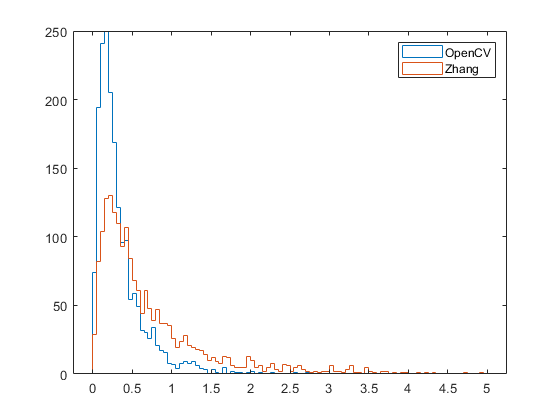

rpes2 = reprojection_errors(A, d, Rs, ts, model_points, image_points);

figure
histogram(rpes1, 100, 'displaystyle', 'stairs', 'BinLimits', [0,5]);
hold on;
histogram(rpes2, 100, 'displaystyle', 'stairs', 'BinLimits', [0,5]);
hold off;
legend('OpenCV', 'Zhang')

As we can see the OpenCV has more of its errors in the low range while Zhang method has a higher as we also could see in the mean square error rpe and rpe2.

**QUESTION 17: Similarly as before with OpenCV, apply undistort_image to '14.jpg'. Produce one normal and one "zoomed out" image. Compare with the results you got previously with OpenCV! **

im = imread('14.jpg');
B = A .*   [1/2,1  ,1;
            1,  1/2,1;
            1,  1,  1];
im4 = undistort_image(A, d, im, B);

%opencv
figure
imshow(im3)

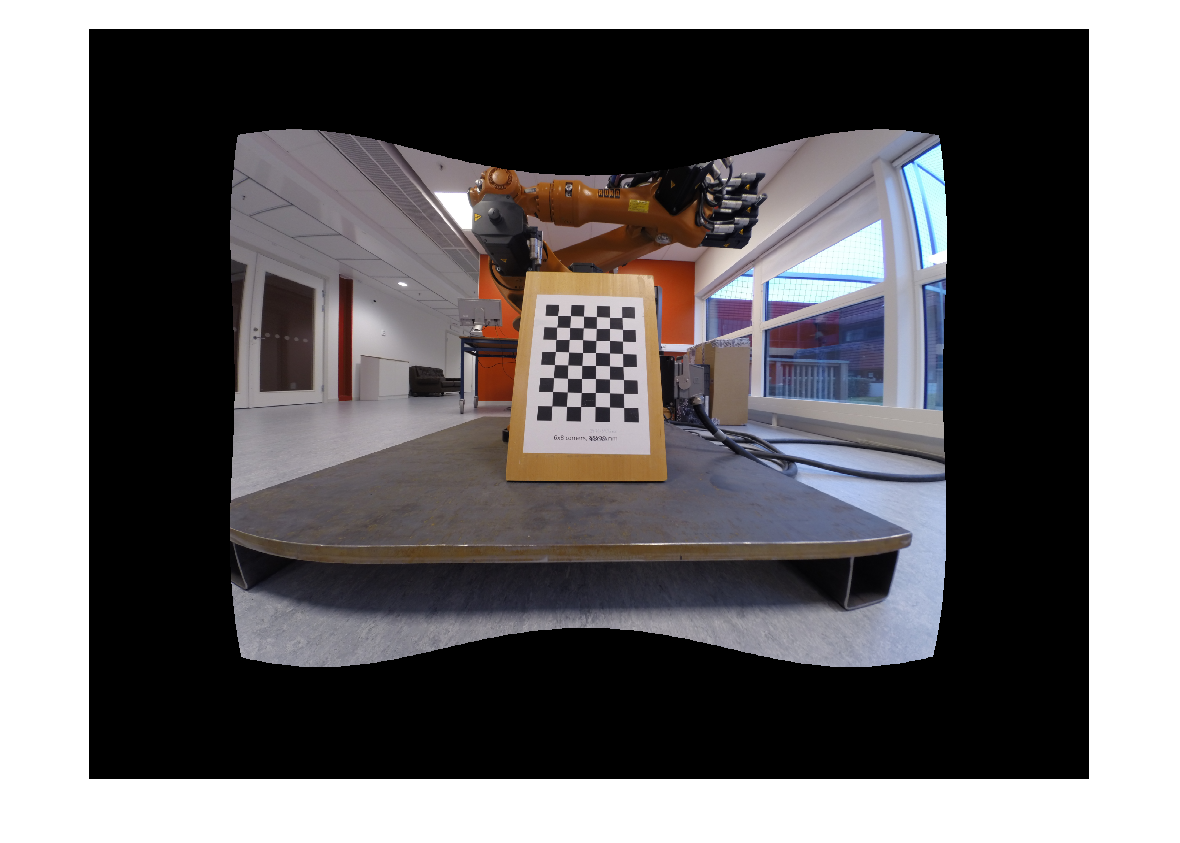


%zhang
figure
imshow(im4)